## **Exercise 6a**

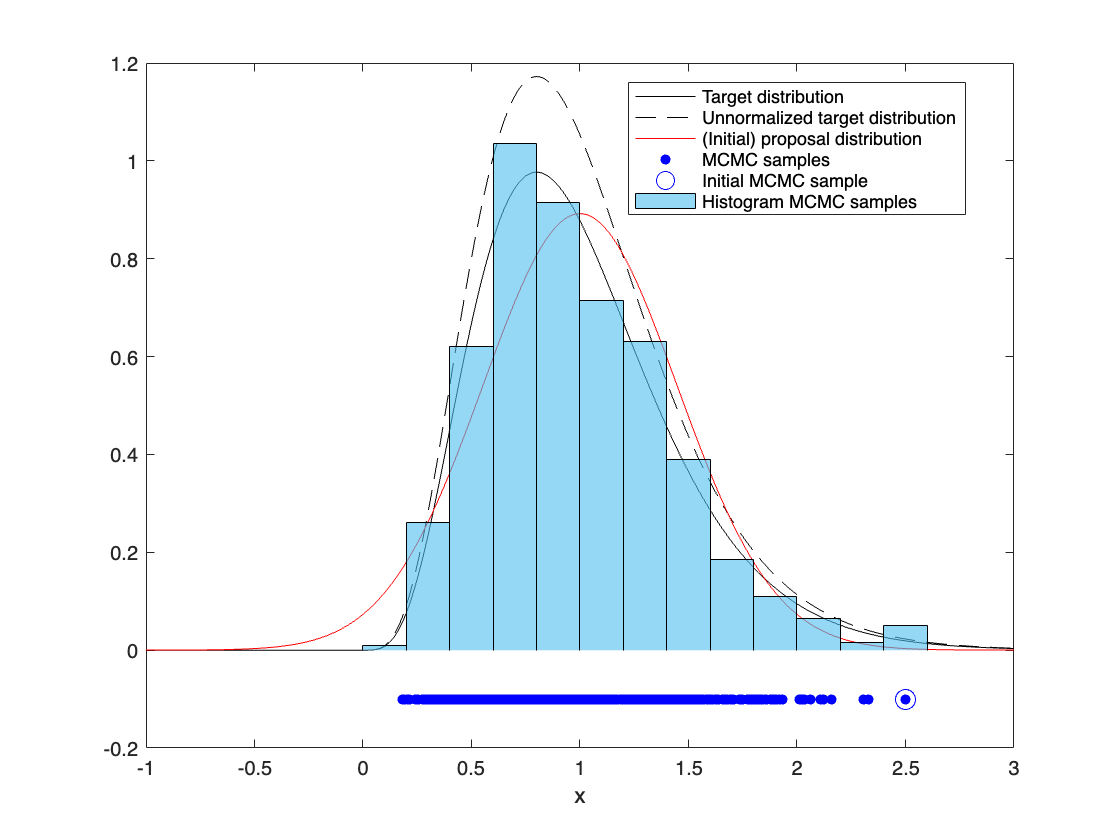

close all
clear
clc

%% Given

target = @(x,n) n^n*x.^(n-1)/factorial(n-1) .* exp(-n*x) .* (x>=0);
unnormalized_target = @(x,n) 1.2*target(x,n);

n = 5;
number_of_samples = 1e3;
initial_sample = 2.5;

%% What you need to implement

% Part a

myNormpdf = @(x, mu, sigma) (1/(sigma*sqrt(2*pi))) * exp(-((x-mu).^2)/(2*sigma^2));
proposal = @(xProposed, xPrevious, n) myNormpdf(xProposed, 1, sqrt(1/5));
sample_from_proposal = @(xPrevious, n) 1 + sqrt(1/5)*randn;
compute_acceptance_probability = @(xProposed, xPrevious, n) ...
    min(1, (unnormalized_target(xProposed, n) * myNormpdf(xPrevious, 1, sqrt(1/5))) / ...
           (unnormalized_target(xPrevious, n) * myNormpdf(xProposed, 1, sqrt(1/5))));

%% The Metropolis-Hastings algorithm

samples = zeros(number_of_samples,1);
proposed_samples = zeros(number_of_samples,1);
acceptance_probability = zeros(number_of_samples,1);
samples(1) = initial_sample;
for i = 2:number_of_samples
    xPrevious = samples(i-1);
    xProposed = sample_from_proposal(xPrevious,n);
    proposed_samples(i) = xProposed;
    acceptance_probability(i) = compute_acceptance_probability(xProposed,xPrevious,n);
    u = rand;
    if u <= acceptance_probability(i)
        samples(i) = xProposed;
    else
        samples(i) = xPrevious;
    end
end

%% Plotting the results

xPlot = linspace(-1,3,1e3);

figure
    plot(xPlot,target(xPlot,n),'k','DisplayName','Target distribution')
    hold on
    plot(xPlot,unnormalized_target(xPlot,n),'k--','DisplayName','Unnormalized target distribution')
    plot(xPlot,proposal(xPlot,initial_sample,n),'r','DisplayName','(Initial) proposal distribution')
    plot(sort(samples),-0.1*ones(length(samples),1),'b.','MarkerSize',15,'DisplayName','MCMC samples')
    plot(initial_sample,-0.1,'bo','MarkerSize',10,'DisplayName','Initial MCMC sample')
    histogram(samples,'Normalization','pdf','DisplayName','Histogram MCMC samples')
    xlabel('x')
    legend('Location','Best')

## **Exercise 6b**

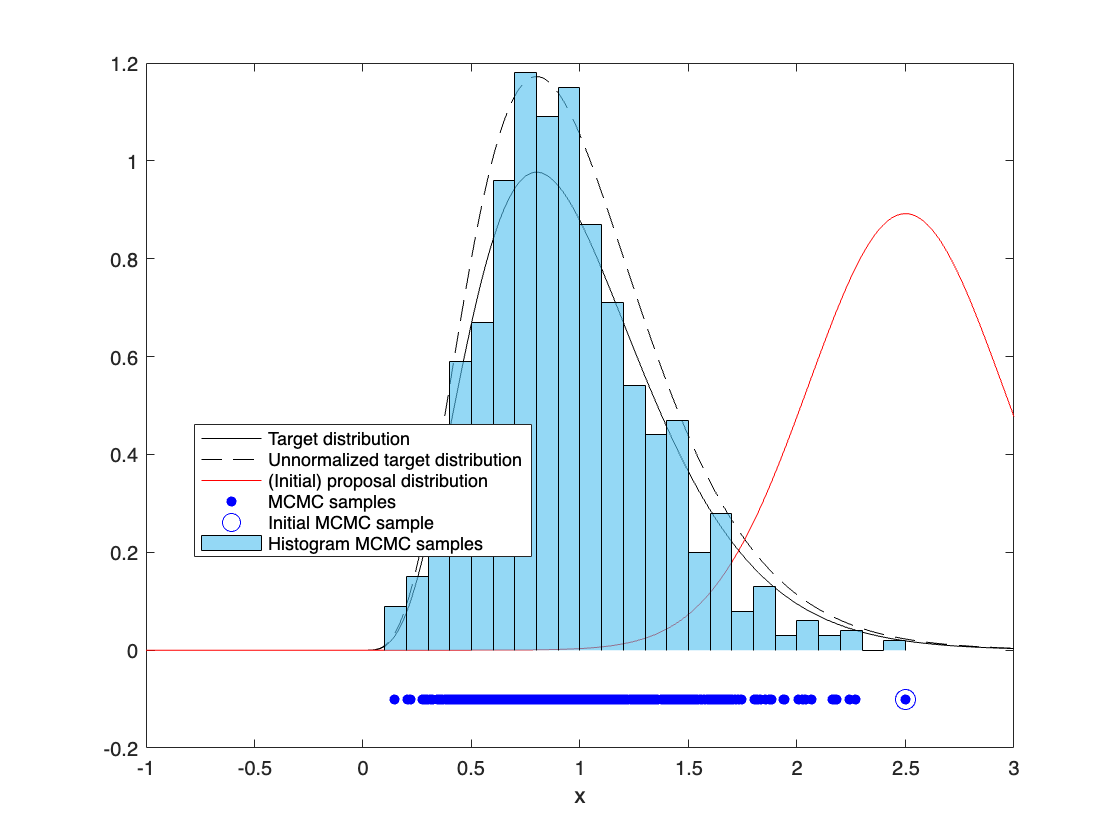

%% Given

target = @(x,n) n^n*x.^(n-1)/factorial(n-1) .* exp(-n*x) .* (x>=0);
unnormalized_target = @(x,n) 1.2*target(x,n);

n = 5;
number_of_samples = 1e3;
initial_sample = 2.5;

%% What you need to implement

% Part b

myNormpdf = @(x, mu, sigma) (1/(sigma*sqrt(2*pi))) * exp(-((x-mu).^2)/(2*sigma^2));
% Set the variance for the random-walk proposal (e.g., variance = 1/5).
sigma = sqrt(1/5);

% Proposal function: now depends on the previous sample.
proposal = @(xProposed, xPrevious, n) myNormpdf(xProposed, xPrevious, sigma);

% Sample from proposal: sample from a normal centered at the previous sample.
sample_from_proposal = @(xPrevious, n) xPrevious + sigma * randn;

% Compute acceptance probability: because the proposal is symmetric,
% the acceptance probability simplifies to:
compute_acceptance_probability = @(xProposed, xPrevious, n) ...
    min(1, unnormalized_target(xProposed, n) / unnormalized_target(xPrevious, n));

%% The Metropolis-Hastings algorithm

samples = zeros(number_of_samples,1);
proposed_samples = zeros(number_of_samples,1);
acceptance_probability = zeros(number_of_samples,1);
samples(1) = initial_sample;
for i = 2:number_of_samples
    xPrevious = samples(i-1);
    xProposed = sample_from_proposal(xPrevious,n);
    proposed_samples(i) = xProposed;
    acceptance_probability(i) = compute_acceptance_probability(xProposed,xPrevious,n);
    u = rand;
    if u <= acceptance_probability(i)
        samples(i) = xProposed;
    else
        samples(i) = xPrevious;
    end
end

%% Plotting the results

xPlot = linspace(-1,3,1e3);

figure
    plot(xPlot,target(xPlot,n),'k','DisplayName','Target distribution')
    hold on
    plot(xPlot,unnormalized_target(xPlot,n),'k--','DisplayName','Unnormalized target distribution')
    plot(xPlot,proposal(xPlot,initial_sample,n),'r','DisplayName','(Initial) proposal distribution')
    plot(sort(samples),-0.1*ones(length(samples),1),'b.','MarkerSize',15,'DisplayName','MCMC samples')
    plot(initial_sample,-0.1,'bo','MarkerSize',10,'DisplayName','Initial MCMC sample')
    histogram(samples,'Normalization','pdf','DisplayName','Histogram MCMC samples')
    xlabel('x')
    legend('Location','Best')